## Controlo Automático - Projecto

%% Inicialização do ambiente
clear ; close all; clc

% Importamos os dados dos pacientes
data = importdata('ROC_REAL_50.mat');

% Definimos uma seed estatica para o gerador de números aleatórios de forma
% a podermos repetir os experimentos com resultados determinísticos
rng(42);

### **Questão 1**

**a)** Selecionamos 10 pacientes da base de dados:

rndIDX = randperm(50);
sample_size = 10

sample_size = 10

sample = data(rndIDX(1:sample_size), :)

sample =     0.0219    1.2746
    0.0528    2.5362
    0.0352    1.5503
    0.0293    1.4728
    0.0308    1.9499
    0.0330    2.4823
    0.0282    1.2615
    0.0295    1.2390
    0.0329    2.5669
    0.0394    2.0425


t_size = 600

t_size = 600

**b) e c)**

Cálculo de $c_e \left(t\right)$ e da respectiva média.

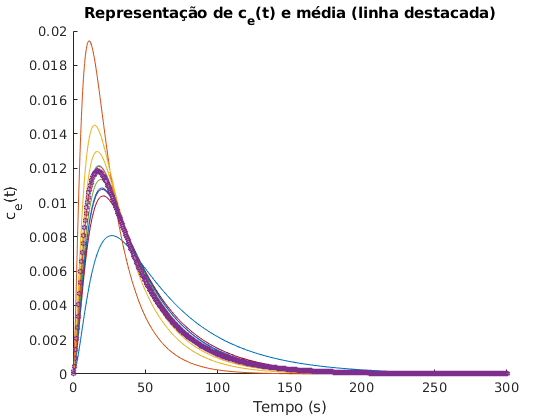

figure(1);
hold on
t = linspace(0, 300, t_size);
Ce = zeros(t_size, sample_size);
s = tf('s');
G = @(a) (40*a^3) / ((s+a)*(s+4*a)*(s+10*a));
for idx = 1 : sample_size
    a = sample(idx, 1);
    Ce(:, idx) = impulse(G(a) * 0.6, t);
end
plot(t, Ce);
alpha = mean(Ce, 2);
plot(t, alpha, 'h', 'MarkerSize', 4)
xlabel('Tempo (s)')
ylabel('c_{e}(t)')
title('Representação de c_{e}(t) e média (linha destacada)')
hold off

Cálculo de $R\left(t\right)$ e da respectiva média.

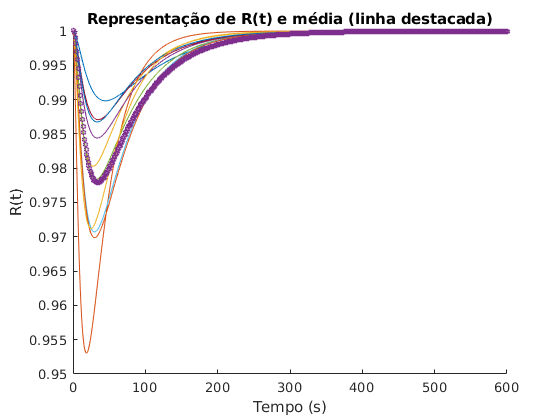

r0 = 1;
EC50 = 1;
figure(2);
hold on
t = linspace(0, 500, t_size);
% O transposto da segunda coluna de `sample` é repetido verticalmente
% `t_size` vezes e multiplicado elemento a elemento com `Ce`
R = r0 ./ (1 + (Ce / EC50) .* repmat(sample(:, 2)', t_size, 1));
plot(t, R);
gamma = mean(R, 2);
plot(gamma, 'h', 'MarkerSize', 4)
xlabel('Tempo (s)')
ylabel('R(t)')
title('Representação de R(t) e média (linha destacada)')
hold off

### **Questão 2**

**a)**

Para calcularmos a estabilidade, recorremos ao critério de estabilidade de Routh-Hurwitz, para isso adaptamos: *Farzad Sagharchi (2020). Routh-Hurwitz stability criterion (https://www.mathworks.com/matlabcentral/fileexchange/17483-routh-hurwitz-stability-criterion), MATLAB Central File Exchange. Retrieved May 25, 2020.* (código alterado em *rhcalculator.m*).

Vamos tomar como vector de coeficientes possível representante do nosso sistema o seguinte:

%a = sample(1,1);
a = -1;
coeffVector = [(1+a) (1+4*a) (1+10*a)]

coeffVector =      0    -3    -9


% Cálculo
rhcalculator

Tabela de Routh-Hurwitz

rhTable

rhTable =      0    -9
    -3     0
    -9     0


Análise da estabilidade

if unstablePoles == 0
    fprintf('É um sistema estável.\n')
else
    fprintf('É um sistema instável!\n')
end

É um sistema estável.


N.B.: Se `a` fosse um valor compreendido contido em [-1,0], teriamos um sistema instável. Isto não acontece no nosso sistema.

Número de polos no lado direito

unstablePoles

unstablePoles = 0

Raizes dos coeficientes do polinómio em causa

roots(coeffVector)

ans = -3